# Load Cell Parsing

## Import Data

clear; clc; close all;
addpath(genpath(pwd));

SENSOR = 21; %12 for hex12, 21 for hex21
TYPE = 0; % 0 for static, 1 for dynamic
RUNG = 1;
TRIAL = 10;

% Combine them into a single string for the switch
combination = sprintf('S%d_Y%d_R%d_T%d',SENSOR, TYPE, RUNG, TRIAL);

[filepath, confirmation_array, cal_domain, strict_cal_domain, zero_domain, golay_framelen, static_domain] = ...
    import_resense_data(combination);
opts = detectImportOptions(filepath);
data = readtable(filepath, opts);

## Define Constants

nominal_sampling_rate = 1000;
cal_force = 0.2.*9.81;
minPeakHeight = 4; %Newtons
golay_order = 4;
peak_domain_radius = 250;
if RUNG == 1
    peak_analytical = 17.7;
elseif RUNG == 2
    peak_analytical = 19.5;
elseif RUNG == 3
    peak_analytical = 13.2;
end

## Format Data as Uniform

raw_time = data.Timestamp; % e.g., 13025702930
raw_force = data.Fz;   % The load cell reading
raw_time = (raw_time - raw_time(1)) ./ 1e6;
raw_force = -1.*raw_force;
%force = force - mean(force(zero_domain));
if ~isempty(zero_domain)
    raw_force = raw_force - mean(raw_force(zero_domain));
else
    raw_force = raw_force - mode(raw_force);
end

[~, uniqueIdx] = unique(raw_time, 'stable');

% re-indexing the table to keep only unique rows
raw_time = raw_time(uniqueIdx, :);
raw_force = raw_force(uniqueIdx, :);

% create uniform force data
time_uniform = 0:(1/nominal_sampling_rate):raw_time(end);

% Interpolate to create a uniform signal
force_uniform = interp1(raw_time, raw_force, time_uniform, 'linear');

## Process Force Signal

% define a uniform sampling rate (Fs)
fft_domain = 1:length(time_uniform);

% Run FFT
Y = fft(force_uniform);

% Compute the magnitude and normalize by signal length L
L = length(force_uniform);
P2 = abs(Y/L);

% Keep only the first half of the symmetric spectrum
num_points = floor(L/2) + 1;
P1 = P2(1:num_points);
P1(2:end-1) = 2*P1(2:end-1);

% 5. Define the Frequency Domain (f)
f = nominal_sampling_rate*(0:(L/2))/L;

% define filter
Fc = 18;        % Cutoff frequency (Hz)
order = 4;      % Filter order (4 is standard for a sharp cutoff)

% 2. Design the filter
% [b, a] are the filter coefficients
[b, a] = butter(order, Fc/(nominal_sampling_rate/2), 'low');

### Select Processing Tool

if isempty(golay_framelen)
    golay_framelen = 81;
end

% apply low pass filter to force data or Savitzky-Golay
%processed_force_uniform = force_uniform; %no filtering
%processed_force_uniform = filtfilt(b, a, force_uniform); %Butterworth
processed_force_uniform = sgolayfilt(force_uniform, golay_order, golay_framelen); %Savitzky-Golay

% Run FFT
Y_processed = fft(processed_force_uniform);

% Compute the magnitude and normalize by signal length L
P2_processed = abs(Y_processed/L);

% Keep only the first half of the symmetric spectrum
num_points = floor(L/2) + 1;
P1_processed = P2_processed(1:num_points);
P1_processed(2:end-1) = 2*P1_processed(2:end-1);

## Graph FFT for Force Data

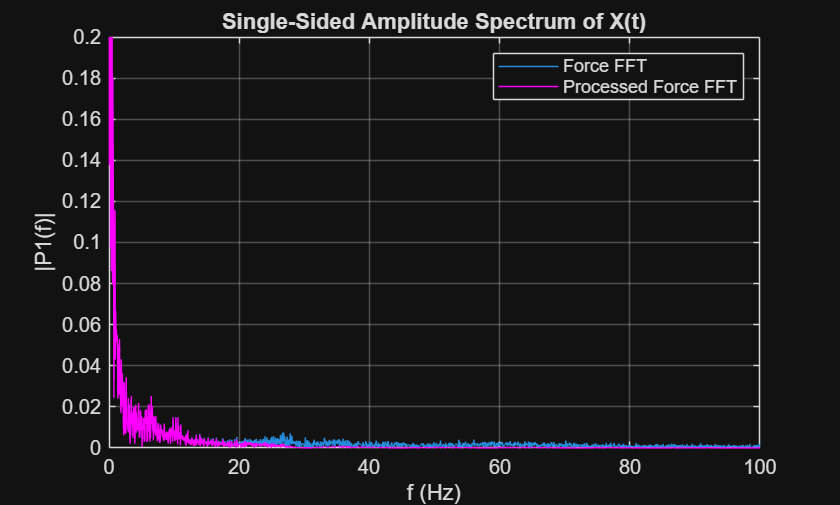

fig(1) = figure;
plot(f,P1);
hold on;
plot(f, P1_processed, 'm');
hold off;
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0 100]);
ylim([0 0.2]);
legend('Force FFT', 'Processed Force FFT', 'Location', 'northeast');
grid on;

## Scale Force Values

measured_cal_force = mean(processed_force_uniform(strict_cal_domain));
compensation_coeff = cal_force/measured_cal_force;

%scale all force values
raw_force = compensation_coeff.*raw_force;
force_uniform = compensation_coeff.*force_uniform;
processed_force_uniform = compensation_coeff.*processed_force_uniform;

## Search for Peaks

minPeakDistance = 1.*nominal_sampling_rate; % seconds
[raw_pks, raw_locs] = findpeaks(raw_force, 'MinPeakHeight', minPeakHeight, 'MinPeakDistance', minPeakDistance);

raw_peak_times = raw_time(raw_locs);
[pks_uniform, locs_uniform] = findpeaks(force_uniform, 'MinPeakHeight', minPeakHeight, 'MinPeakDistance', minPeakDistance);

uniform_peak_times = time_uniform(locs_uniform);
[pks_processed, locs_processed] = findpeaks(processed_force_uniform, 'MinPeakHeight', minPeakHeight, 'MinPeakDistance', minPeakDistance);

processed_peak_times = time_uniform(locs_processed);

### Display Average Peak Values

%avg_raw_peak = mean(raw_pks);
avg_uniform_peak = mean(pks_uniform);
%avg_processed_peak = mean(pks_processed);
avg_static_force = mean(processed_force_uniform(static_domain))

avg_static_force = 1.2457

confirmed_raw_peaks = raw_pks(confirmation_array);
confirmed_raw_peak_times = raw_peak_times(confirmation_array);
confirmed_processed_peaks = pks_processed(confirmation_array);
confirmed_processed_peak_times = processed_peak_times(confirmation_array);
if TYPE == 1
    first_peak_index = locs_processed(2);
else
    first_peak_index = [];
end
processed_peak_domain = first_peak_index-peak_domain_radius:first_peak_index+peak_domain_radius;
if TYPE == 1
    first_raw_peak_index = raw_locs(2);
else
    first_raw_peak_index = [];
end
raw_peak_domain = first_raw_peak_index-peak_domain_radius:first_raw_peak_index+peak_domain_radius;

### Display Peaks

#### Raw

fprintf('Found %d raw peaks in the dataset.\n', length(confirmed_raw_peaks));

Found 0 raw peaks in the dataset.


confirmed_raw_peak_table = table(confirmed_raw_peak_times, confirmed_raw_peaks, 'VariableNames', {'Time_s', 'Force_Value'});
disp(confirmed_raw_peak_table);

    Time_s    Force_Value
    ______    ___________




avg_raw_peak = mean(confirmed_raw_peaks)

avg_raw_peak = NaN

#### Processed

fprintf('Found %d processed peaks in the dataset.\n', length(confirmed_processed_peaks));

Found 0 processed peaks in the dataset.


confirmed_processed_peak_table = table(confirmed_processed_peak_times', confirmed_processed_peaks', 'VariableNames', {'Time_s', 'Force_Value'});
disp(confirmed_processed_peak_table);

    Time_s    Force_Value
    ______    ___________




avg_processed_peak = mean(confirmed_processed_peaks)

avg_processed_peak = NaN

### Graph Peaks

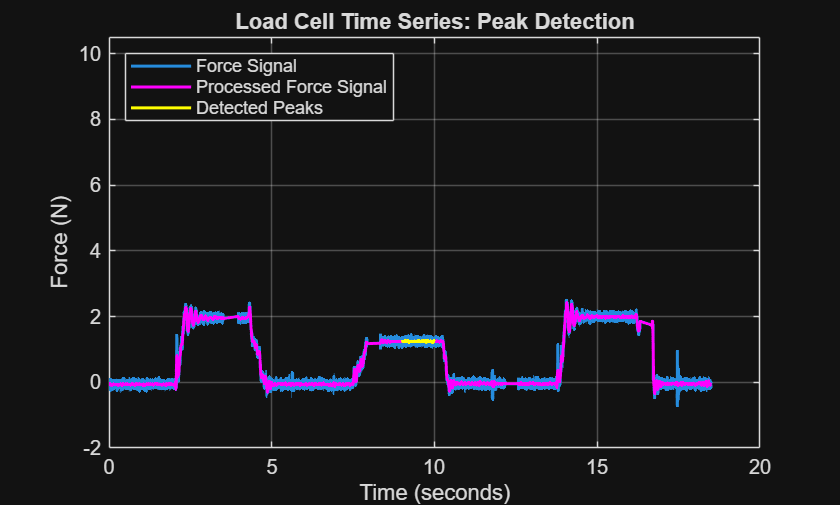

fig(2) = figure;
plot(raw_time, raw_force, 'LineWidth', 1.5);
hold on;
plot(time_uniform, processed_force_uniform, 'm', 'LineWidth', 1.5);
plot(uniform_peak_times, pks_uniform, 'rv', 'MarkerFaceColor', 'r'); % Red triangles at peaks
plot(confirmed_processed_peak_times, confirmed_raw_peaks + 0.5, 'gv', 'MarkerFaceColor', 'g'); % Red triangles at peaks
plot(time_uniform(static_domain), processed_force_uniform(static_domain), 'y', 'LineWidth', 1.5);
grid on;
hold off;
xlabel('Time (seconds)');
ylabel('Force (N)');
ylim([-2 max(raw_force)+8]);
title('Load Cell Time Series: Peak Detection');
legend('Force Signal', 'Processed Force Signal', 'Detected Peaks', 'Confirmed Peaks', 'Location', 'northwest');

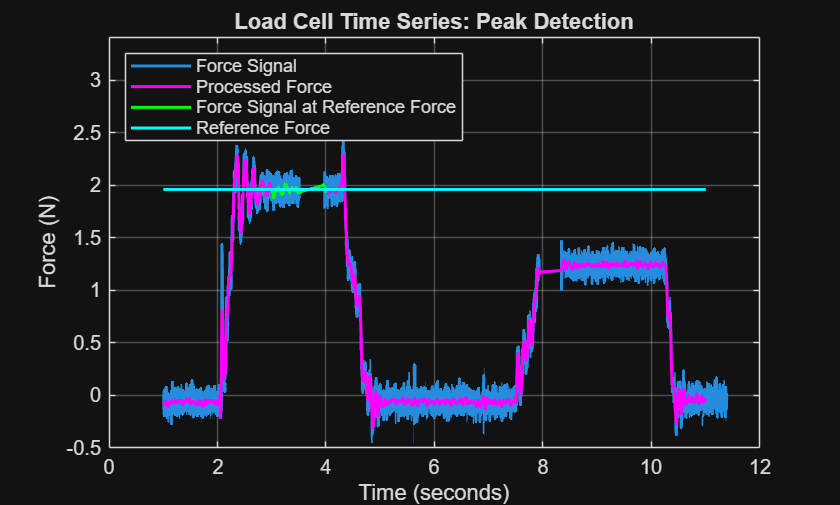

fig(3) = figure;
plot(raw_time(cal_domain), raw_force(cal_domain), 'LineWidth', 1.5);
hold on;
plot(time_uniform(cal_domain), processed_force_uniform(cal_domain), 'm', 'LineWidth', 1.5);
plot(time_uniform(strict_cal_domain), processed_force_uniform(strict_cal_domain), 'g', 'LineWidth', 1.5)
plot(time_uniform(cal_domain), cal_force.*ones(1,length(cal_domain)), 'c', 'LineWidth', 1.5);
grid on;
hold off;
xlabel('Time (seconds)');
ylabel('Force (N)');
ylim([-0.5 max(raw_force(cal_domain))+1]);
title('Load Cell Time Series: Peak Detection');
legend('Force Signal', 'Processed Force', 'Force Signal at Reference Force', 'Reference Force', ...
    'Location', 'northwest');

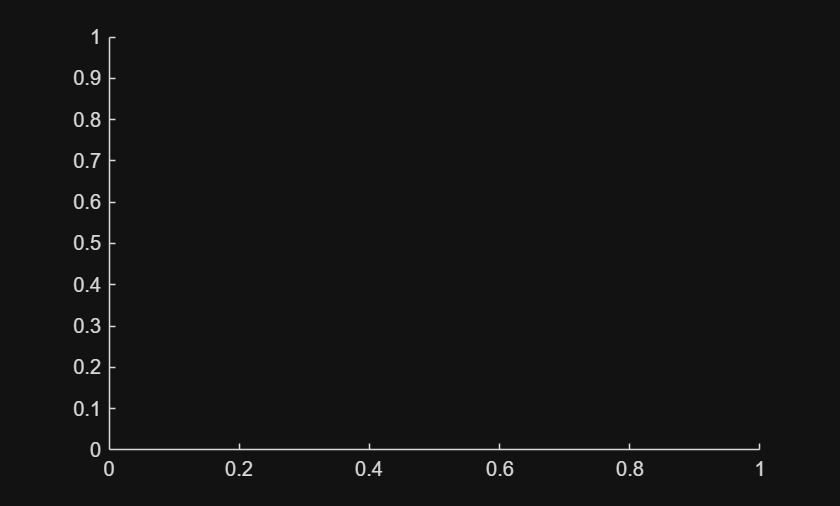

fig(4) = figure;
plot(raw_time(raw_peak_domain), raw_force(raw_peak_domain), 'LineWidth', 1.5);
hold on;

plot(time_uniform(processed_peak_domain), processed_force_uniform(processed_peak_domain), '-m', 'LineWidth', 1.5);
plot([time_uniform(processed_peak_domain(1)) time_uniform(processed_peak_domain(end))], ...
    [peak_analytical peak_analytical], '--g', 'LineWidth', 1.5);

Index exceeds array bounds.

grid on;
hold off;
xlabel('Time (seconds)');
ylabel('Force (N)');
ylim([min(raw_force(raw_peak_domain))-2 max(raw_force(raw_peak_domain))+10]);
xlim([time_uniform(processed_peak_domain(1)) time_uniform(processed_peak_domain(end))]);
title('Force During Impact on Target Cube');
legend('Force Signal', 'Processed Force Signal', 'Estimated Peak from Analytical Calculation', 'Location', 'northeast');
theme(fig(4), "light");
saveas(fig(4), 'images/peak_behavior_' + string(combination) + '.png');

## Check Sampling Rate

instant_period = ones(length(raw_time) - 1,1);
for i = 1:length(raw_time) - 1
    instant_period(i) = raw_time(i+1) - raw_time(i);
end
instant_fq = 1./instant_period;

### Sampling Statistics:

smoothed_fq = instant_fq(instant_fq < 2000);
avg_fq = mean(smoothed_fq)
stdev_fq = std(smoothed_fq)

### Graph Frequency Histogram

fig(5) = figure;
freq_label = "Sampling Frequency (Hz)";
occur_label = "Number of Occurances";
fq_lowest_pass = instant_fq(instant_fq < 2000);
histogram(fq_lowest_pass, 30);
xlabel(freq_label);
ylabel(occur_label);